## Read File

 clear
[m, fs] = audioread('4m.wav');	% load an audio file
x = m(:, 1:3);                    	% get the mic + geo channel
N = length(x);                   	% signal length
to = (0:N-1)/fs;                    % time vector

## Oscillogram

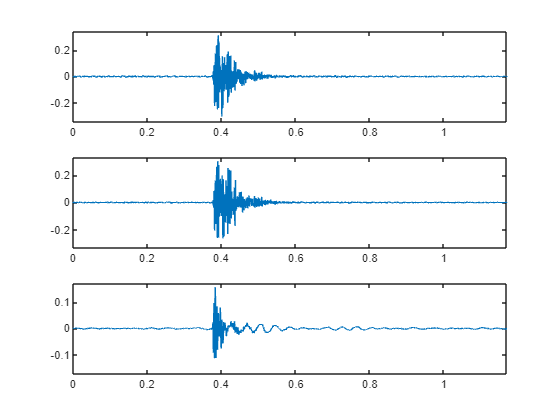

close all
hold on
figure(1)

subplot(3,1,1)
plot(to,x(:,1))
xlim([0 max(to)])
ylim([-1.1*max(abs(x(:,1))) 1.1*max(abs(x(:,1)))])

subplot(3,1,2)
plot(to,x(:,2))
xlim([0 max(to)])
ylim([-1.1*max(abs(x(:,2))) 1.1*max(abs(x(:,2)))])

subplot(3,1,3)
plot(to,x(:,3))
xlim([0 max(to)])
ylim([-1.1*max(abs(x(:,3))) 1.1*max(abs(x(:,3)))])

## Window ReFinement

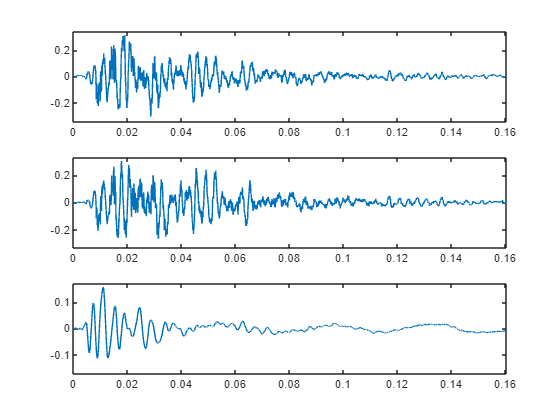

x(1:find(x(:,3)>max(abs(x(:,3)))*0.1,1,'first')-200,:)=[];
x(find(x(:,3)>max(abs(x(:,3)))*0.1,1,'last')+1000:length(x(:,3)),:)=[];
N = length(x);                   	% signal length
to = (0:N-1)/fs;
close all
figure(2)

subplot(3,1,1)
plot(to,x(:,1))
xlim([0 max(to)])
ylim([-1.1*max(abs(x(:,1))) 1.1*max(abs(x(:,1)))])

subplot(3,1,2)
plot(to,x(:,2))
xlim([0 max(to)])
ylim([-1.1*max(abs(x(:,2))) 1.1*max(abs(x(:,2)))])

subplot(3,1,3)
plot(to,x(:,3))
xlim([0 max(to)])
ylim([-1.1*max(abs(x(:,3))) 1.1*max(abs(x(:,3)))])

audiowrite('r4m.wav',x,fs);